# `统计学习方法 第一章 测试`

# **Linear-l**`east-squares Curve Fitting` 

(广东工业大学 自动化学院 控制科学与工程 学一 黄国盛 2112004086  2020.11.28）

% 线性最小二乘法拟合主要是polyfit函数，而polyfit函数的核心是qr函数，即 QR decomposition algorithm ！ 
% 最核心的算法其实是：QR分解 
% So, where to find source code of qr() of MATLAB ！！！   [leastsq() of Python ]
clear all;
clc ;
close all;

OriginalX = 0:0.001:2*pi;
OriginalY = sin(OriginalX);

RealX = 0:0.35:2*pi;
RealY = sin(RealX);
ObseNoise_VAR = 0.01; % 观测噪声的方差 ObserveNoise_VAR   
% 观测噪声: sqrt(ObseNoise_VAR)*randn(1,length(RealX))  工程上采用 高频n次采样均值 降低检测误差
ObserY = RealY + sqrt(ObseNoise_VAR)*randn(1,length(RealX));% + 0.1; % 偏移 用于核对拟合效果

FittingPoint_Count = length(RealX)

FittingPoint_Count =     18

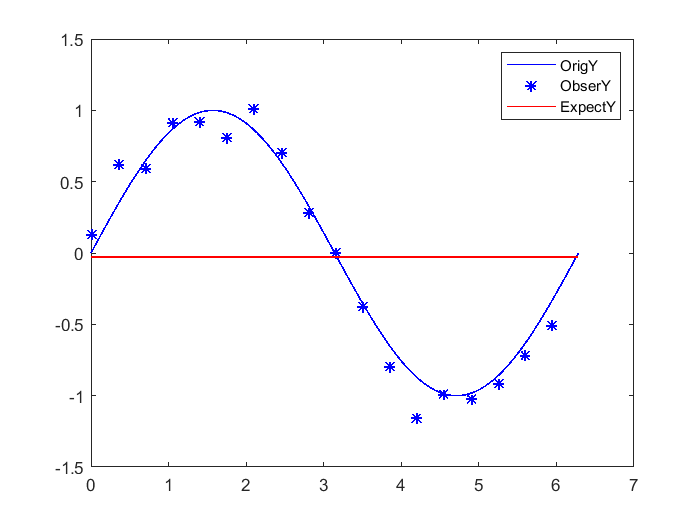

coef = polyfit(RealX,ObserY,0);  % 
ExpectY = polyval(coef,OriginalX);
plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
legend('OrigY', 'ObserY', 'ExpectY');

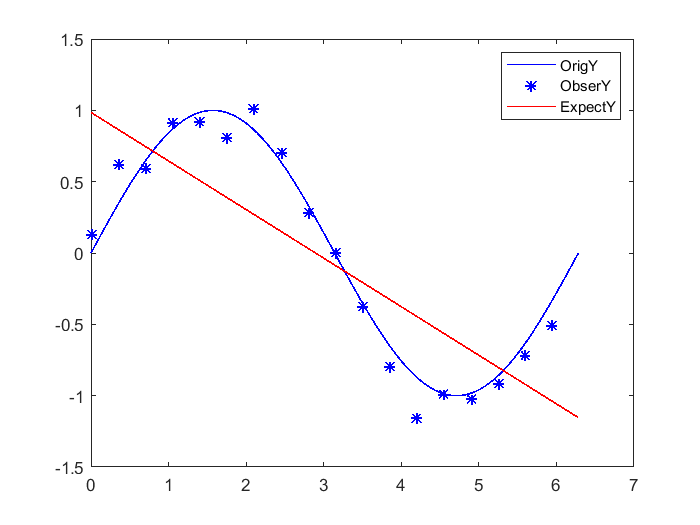


coef = polyfit(RealX,ObserY,1);  %
ExpectY = polyval(coef,OriginalX);
plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
legend('OrigY', 'ObserY', 'ExpectY');

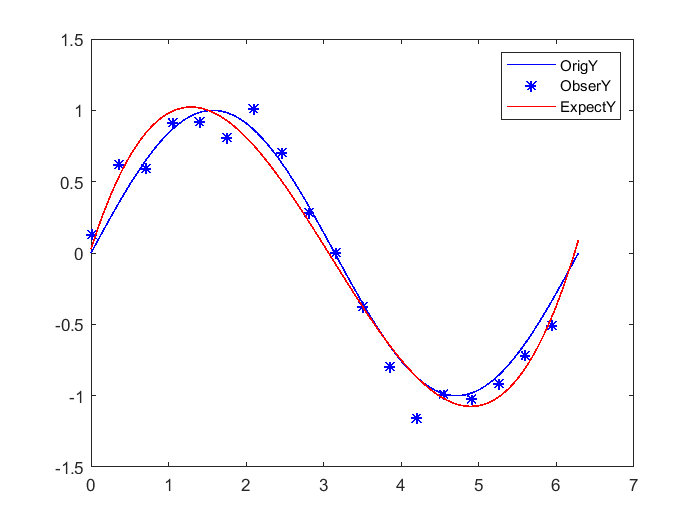


coef = PolyFit_III(RealX,ObserY);  % 三次基本足够 
ExpectY = polyval(coef,OriginalX); % 在硬件C上最好不要超过四次 并且变量都需强转为single以提高速度并节省内存
    plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
    legend('OrigY', 'ObserY', 'ExpectY');

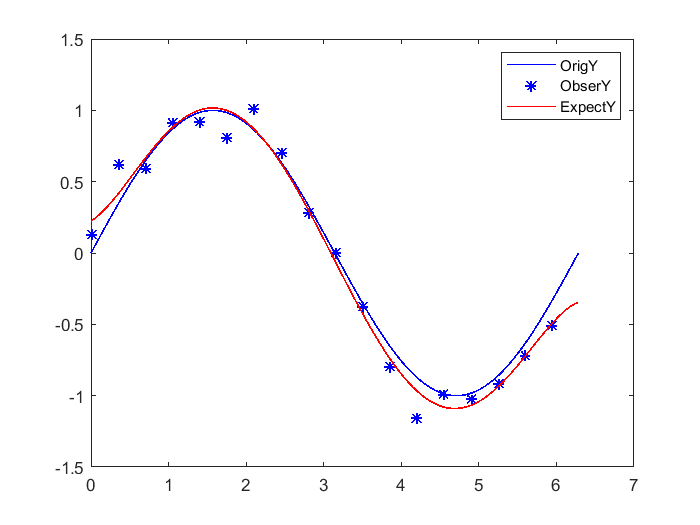

coef = PolyFit_V(RealX,ObserY);  % 
ExpectY = polyval(coef,OriginalX);
    plot(OriginalX,OriginalY,'b',RealX,ObserY,'b*',OriginalX,ExpectY,'r','LineWidth',1)
    legend('OrigY', 'ObserY', 'ExpectY');

function [p] = PolyFit_III(fit_x,fit_y)
    x = fit_x';
    y = fit_y';

    V(:,4) = ones(length(x),1,class(x));

    for j = 3:-1:1 % 3 2 1
        V(:,j) = x .*  V(:,j+1);
    end
 
    % Solve least squares problem p = V\y to get polynomial coefficients p.
    % 线性最小二乘法拟合实现的核心：QR分解，Python亦如此
    % 这里是数值分析和矩阵分析的知识
     [Q,R] = qr(V,0);   %  V=QR   其中 QTQ = I, R是上三角矩阵
    %[Q,R] = qrhhr(V);
    
    p = R\(Q'*y);
    
    p = p.';  
end


function [p] = PolyFit_V(fit_x,fit_y)
    x = fit_x';
    y = fit_y';

    V(:,6) = ones(length(x),1,class(x));

    for j = 5:-1:1 % 3 2 1
        V(:,j) = x .*  V(:,j+1);
    end
 
    % Solve least squares problem p = V\y to get polynomial coefficients p.
    [Q,R] = qr(V,0);   %  V=QR   其中 QTQ = I, R是上三角矩阵
 
    p = R\(Q'*y);
    
    p = p.';  
end